
% figure R v.s. Different Work %

clear all;
close all;

load('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsI.mat');
yI = y1;
ymI = y_mean1;
eI = err1;
emI = 2e-6;   % err_mean1

load('D:\MATLAB_Git\MATLAB-atomic-calculation\Comag_Pub\Fig3\RvsDensity.mat');
yD = y1;
ymD = y_mean1;
eD = err1;
emD = 4e-6;

clearvars -except yI ymI eI emI yD ymD eD emD

y1 = [yI,yD];
e1 = [eI,eD];
w1 = 1./e1.^2;
ym1 = sum(w1.*y1)/sum(w1);   % 0.726074(5)
em1 = sqrt( sum( w1.*((y1-ym1).^2+1./w1) ) / sum(w1) );

y2 = [ymI,ymD];
e2 = [emI,emD];
w2 = 1./e2.^2;
ym2 = sum(w2.*y2)/sum(w2);   % 0.726076(3)
em2 = sqrt( sum( w2.*((y2-ym2).^2+1./w2) ) / sum(w2) );



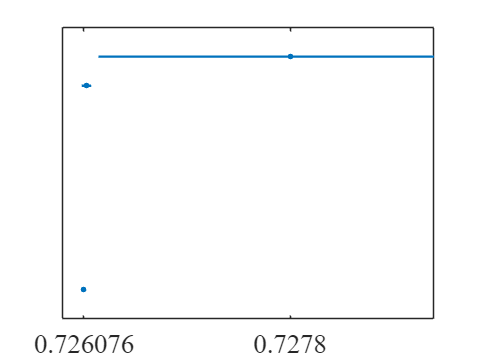


y = [4.5 4 0.5];
x = [0.7278 0.72610 ym2];
err = [16e-4 4e-5 em2];

f1 = figure;
e1 = errorbar(x,y,err,"horizontal",'.','CapSize',0,...
    'LineWidth',1.4,'MarkerSize',10);
set(gca,'FontName','times new roman','FontSize',16);

xlim([0.7259 0.729]);
ylim([0 5]);
xticks([ym2  0.7278]);
xticklabels({'0.726076'  '0.7278'});
yticks([]);


x_min = 0.1;            % 横轴刻度最小值
x_interval = 0.1;       % 横坐标两个刻度间隔距离
x_break_start = 0.5; % 截断的开始值
x_break_end = 0.9;  % 截断的结束值

xlimit=get(gca,'xlim');
location_X=(x_break_start+adjust_value-xlimit(1))/diff(xlimit);

函数或变量 'adjust_value' 无法识别。

t1=text(location_X, 0,'//','sc','BackgroundColor','w','margin',eps, 'fontsize',13);
t2=text(location_X, 1,'//','sc','BackgroundColor','w','margin',eps, 'fontsize',13);
 
% 重新定义横坐标刻度
xtick=x_min:x_interval:x_max_new;
set(gca,'xtick',xtick);
xtick(xtick>x_break_start+eps)=xtick(xtick>x_break_start+eps)+x_break_end-x_break_start;
for i=1:length(xtick)
   xticklabel{i}=sprintf('%.1f',xtick(i));
end
set(gca,'xTickLabel', xticklabel, 'FontSize', 12, 'FontName', 'Times New Roman');   %修改坐标名称、字体
text( 'string',"(a) ", 'Units','normalized','position',[0.05,0.95],  'FontSize',14,'FontWeight','Bold','FontName','Times New Roman');   
set(gca,'Layer','top','FontSize',12,'Fontname', 'Times New Roman');
